# Mobile robot short Project

Authors: Ana Siesto Pérez and Xavier Marti Llull

Team: G11-A

Shared Link with the teacher: [https://drive.matlab.com/sharing/bfe7e5c6-3b20-43d3-9f90-27cd7a658e06](https://drive.matlab.com/sharing/bfe7e5c6-3b20-43d3-9f90-27cd7a658e06) 

Given the kown workspace: Sensors_Data.mat, Laser_Data_CV__d_b.mat and  Enviroment.png

Answer the following question:

## Pose estimation (10%)

Before start:

- Open the Simulink model EKF_Pose_estimation.slx and get familiar with: 'Where2Find_Code.pdf'. 

- Have a look to section See an animation of the file: 3_MR_SP_support.mlx 

Every thing is done, the exercise consist in compile in a mlx file all the concepts.

## 1.- Implement in this mlx file:

ProcNoiseTheta = 9.0000e-06

Ts = 0.0200

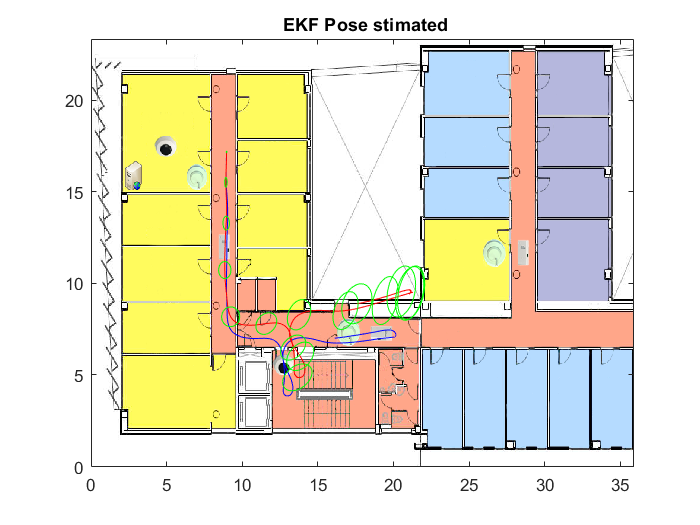

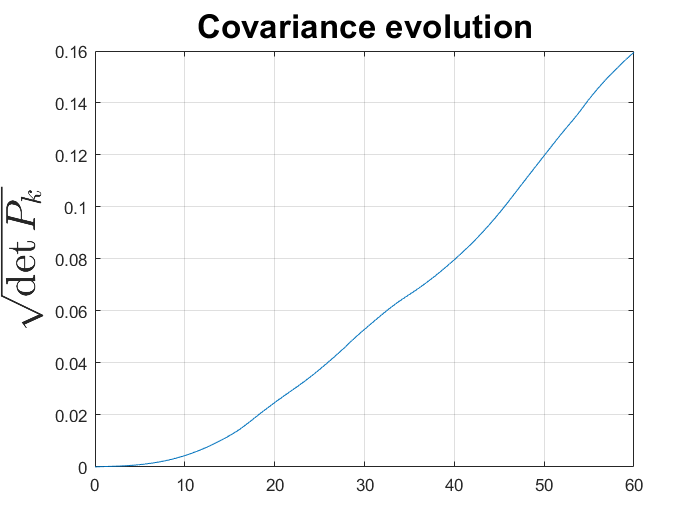

clear
close all
load('Sensors_Data.mat')
load('Laser_Data_CV__d_b.mat')
sim("EKF_Pose_estimation_1.slx");

### a) Pose_theoric, asumme no noise. (review **Mobile Robot Kinematics** folder)

Tf = 60.08;
Ts = 0.02;
W = 0.52;
Gear_ratio = 100;
r = 0.1;

R_inc = right_angular_speed(:, 2) / Gear_ratio * r * Ts;
L_inc = left_angular_speed(:, 2) / Gear_ratio * r * Ts;
R_acu = [right_angular_speed(:, 1), cumsum(R_inc)];
L_acu = [left_angular_speed(:, 1), cumsum(L_inc)];

t=linspace(0,Tf,length(R_acu(:,2)))';
delta_d=(R_inc+L_inc)/2;
delta_t=(R_inc-L_inc)/W;

Initial_pose=transl(8.95,17.2,0)*trotz(-pi/2);
Initial_position=transl(Initial_pose);
Initial_orientation=-pi/2;

% Pose theoric
x(1) = Initial_position(1);
y(1) = Initial_position(2);
o(1) = Initial_orientation;

### b) Pose_estimation by adding noise in odometry. review **Pose uncertanty** folder)

% Pose estimation
V = [3.61e-4 0; 0 9e-6];                 % Noise
noise_d = V(1, 1);
noise_t = V(2, 2);
x_est(1) = Initial_position(1);
y_est(1) = Initial_position(2);
o_est(1) = Initial_orientation;
for i=1:(length(t)-1)

    x(i+1) = x(i) + delta_d(i) * cos(o(i));
    y(i+1) = y(i) + delta_d(i) * sin(o(i));
    o(i+1) = o(i) + delta_t(i);

    x_est(i+1) = x_est(i) + (delta_d(i) + randn*sqrt(noise_d)) * cos(o(i) + randn*sqrt(noise_t));
    y_est(i+1) = y_est(i) + (delta_d(i) + randn*sqrt(noise_d)) * sin(o(i) + randn*sqrt(noise_t));
    o_est(i+1) = o(i) + delta_t(i) + randn*sqrt(noise_t);
end

Pose_theoric = [x; y; o];
% Here we use the data provided by the slx in order to have the same Pose_estimation
% than the teacher (the random numbers were generating a different path for
% us and it is preferable to have the same)
Pose_estimation = [Pose_est.Data(:,1)';Pose_est.Data(:,2)';Pose_est.Data(:,3)']

Pose_estimation =     8.9501    8.9500    8.9501    8.9500    8.9503    8.9504    8.9504    8.9504    8.9505    8.9508    8.9505    8.9509    8.9512    8.9511    8.9510    8.9507    8.9506    8.9506    8.9506    8.9504    8.9503    8.9504    8.9504    8.9505    8.9507    8.9507    8.9507    8.9507    8.9507    8.9507    8.9507    8.9506    8.9506    8.9506    8.9503    8.9501    8.9499    8.9502    8.9499    8.9499    8.9498    8.9493    8.9491    8.9491    8.9493    8.9491    8.9484    8.9482    8.9488    8.9493
   17.1652   17.1488   17.1736   17.1671   17.1145   17.0568   17.0580   17.0619   17.0336   17.0067   17.0296   16.9987   16.9790   16.9839   16.9981   17.0191   17.0328   17.0038   17.0165   17.0482   17.0512   17.0434   17.0422   17.0280   17.0040   16.9996   17.0177   16.9853   16.9749   16.9501   16.9456   16.9206   16.9145   16.9242   16.8751   16.8565   16.8350   16.8571   16.8426   16.8412   16.8308   16.7957   16.7773   16.7766   16.7931   16.7854   16.7308   16.7217 

### c) Ricatti equation for estimating the covariance matrix representing the uncertanty in the robot pose. 

% Calcultaing the Jacobians

F_x = zeros([3,3,3004]);
F_x(1,1,:) = 1; F_x(2,2,:) = 1; F_x(3,3,:) = 1;
F_x(1,3,:) = -delta_d .* sin(o(:));
F_x(2,3,:) =  delta_d .* cos(o(:));

F_v = zeros([3 2 3004]);
F_v(3,2,:) = 1;
F_v(1,1,:) = cos(o(:));
F_v(2,1,:) = sin(o(:));

Pk = zeros([3 3 3004]);
Pk(:,:,1) = eye(3) * 0.0001;

for i=2:3004
    Pk(:,:,i) = F_x(:,:,i)*Pk(:,:,i-1)*F_x(:,:,i)' + F_v(:,:,i)*V*F_v(:,:,i)';
end

## 2.- Display in a figure:

### a) x,y poses for both trajectories: theoric and estimated 

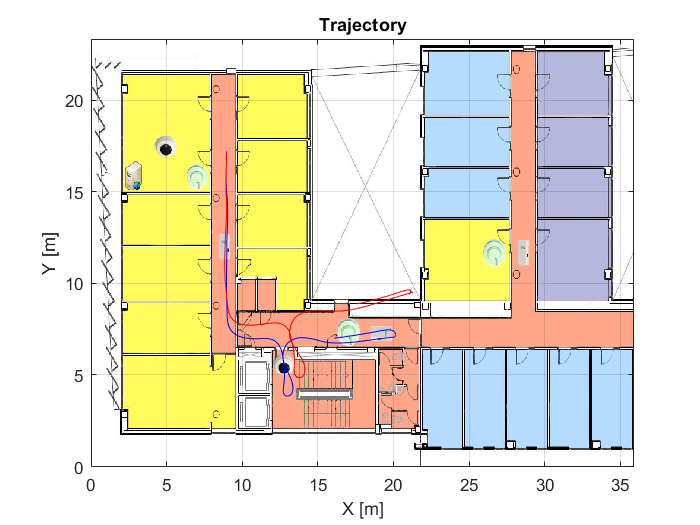

figure
I=imread('Enviroment.png');                 % Read environment
x_ima=[0 35.9];                             
y_ima=[23.31 0];
image(I,'XData',x_ima,'YData',y_ima);       
axis xy
grid on
title('Trajectory')
xlabel ('X [m]')
ylabel ('Y [m]')
hold on

plot(Pose_theoric(1,:), Pose_theoric(2,:), 'b')         % Display a) Pose_theoric
plot(Pose_estimation(1,:), Pose_estimation(2,:), 'r')     % Display b) Pose_estimation
hold off

### b) ellipses representing x,y uncertanty. Do it every 15-20 poses.

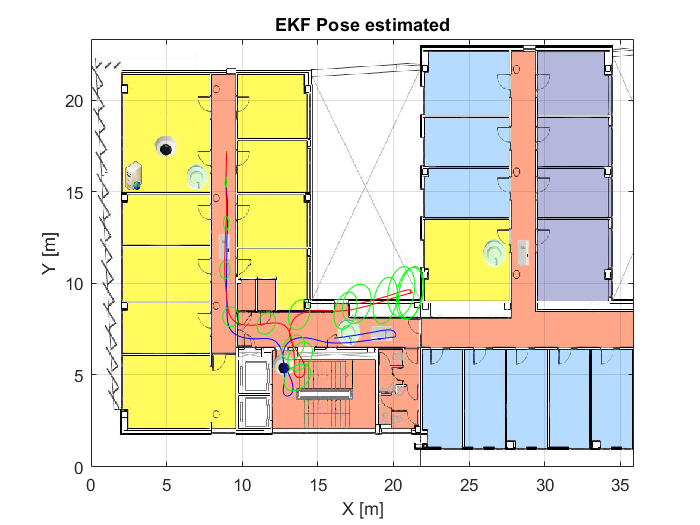

figure
image(I,'XData',x_ima,'YData',y_ima);
title('Trajectory')
axis xy
grid on
xlabel ('X [m]')
ylabel ('Y [m]')
hold on
plot(Pose_theoric(1,:), Pose_theoric(2,:), 'b')         % Display a) Pose_theoric
plot(Pose_estimation(1,:), Pose_estimation(2,:), 'r')     % Display b) Pose_estimation

for i=1:round(length(Pose_t.Data)/15):length(Pose_t.Data)

    plot_ellipse(Pk(1:2,1:2,i),[Pose_estimation(1,i), Pose_estimation(2,i)],'g');
    title('EKF Pose estimated');
end

hold off

### c) represent uncertanty in orientation by adding a isosceles triange in front of the robot the base

video = VideoWriter('uncertanty_theoric.avi');
video.FrameRate = 10;
video.Quality = 100;
open(video);
Robot = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];
Triangle = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];
for i=1:20:(length(t)-1)
    clf
    image(I,'XData',x_ima,'YData',y_ima);       % Display environment
    axis xy
    grid on
    title('Trajectory')
    xlabel ('X [m]')
    ylabel ('Y [m]')
    hold on
    plot(Pose_theoric(1,:), Pose_theoric(2,:), 'b')         % Display a) Pose_theoric
    plot(Pose_estimation(1,:), Pose_estimation(2,:), 'r')     % Display b) Pose_estimation

    Triangle_uncertanty = Triangle;
    e = Pk(:, :, i);
    aux1 = Triangle_uncertanty(3, 2) * sqrt(det(e(1:2, 1:2)));
    aux2 = Triangle_uncertanty(1, 2) * sqrt(det(e(1:2, 1:2)));
    Triangle_uncertanty(3, 2) = aux1;
    Triangle_uncertanty(1, 2) = aux2;

    Robot_pose = transl(x(i), y(i), 0) * trotz(o(i));
    Robot_final = Robot_pose * Robot';
    Triangle_final = Robot_pose * transl(0.5, 0, 0) * trotz(pi) * Triangle_uncertanty';

    rob = patch(Robot_final(1, :), Robot_final(2, :), 'r');
    tri = patch(Triangle_final(1, :), Triangle_final(2, :), 'yellow');

    pause(0.2);

    frame = getframe(gcf);
    writeVideo(video, frame);
    delete(rob);
    delete(tri);
end

close(video)

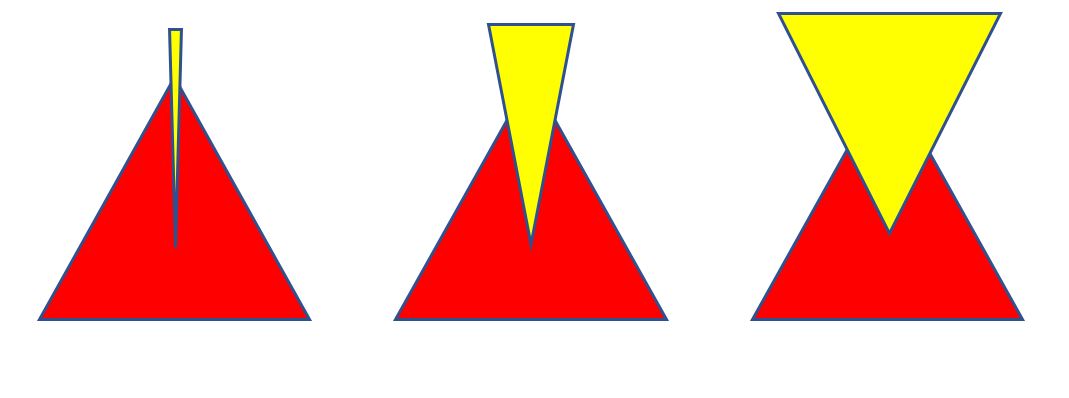

The robot will be represented by a triangle: Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]

Record a movie of the robot moving along the corridor displaying both trajectories.

 See: help VideoWriter to get familiar with the matlab functions

## Laser data (10%)

Make a movie of laser data in Robot reference frame.

copy here the code of the last TODO Lab about laser data. See the video  of ATENEA: [Movie of the Laser Data seen in Robot Reference FrameURL](https://atenea.upc.edu/mod/url/view.php?id=3257292)

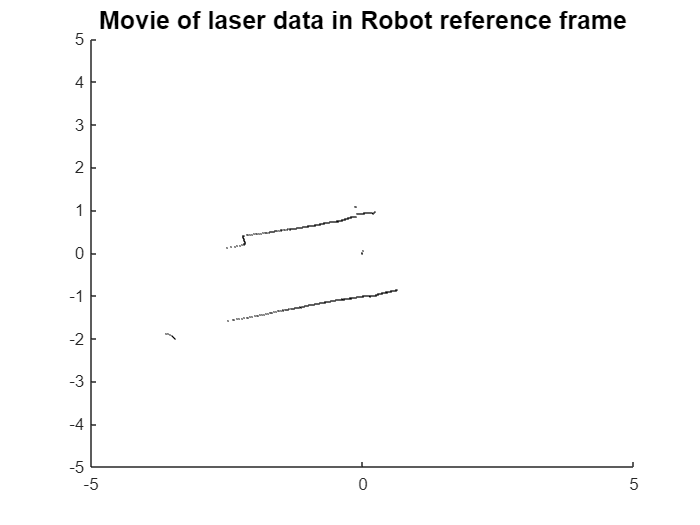

video = VideoWriter('mapping.avi');
video.FrameRate = 20;
video.Quality = 100;
open(video);
Robot = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];

for k=1:6:(length(t)-1)
    clf
    Robot_pose = transl(x(k), y(k), 0) * trotz(o(k));
    Robot_final = Robot_pose * Robot';
    
    if (mod(k, 6) == 1)
        clear x2 y2
        count = 1;
        m = size(polar_laser_data);
        i = ceil(k/20.1611);
        for j=1:(m(2)-1)
            if polar_laser_data(i, j) / 1000 > 0
                alpha = (j-1) * 0.3515;
                alpha = o(20 * (i-1) + 1) - 120 * pi/180 + alpha * pi/180;
                x2(count) = (polar_laser_data(i, j) / 1000) * cos(alpha);
                y2(count) = (polar_laser_data(i, j) / 1000) * sin(alpha);
                count = count + 1;
            end
        end
    end

    scatter(x2, y2, 1, '.', 'black');
    axis([-5 5 -5 5]);
    title("Movie of laser data in Robot reference frame", 'FontSize',15);
    pause(0.2)   
    
    frame = getframe(gcf);
    writeVideo(video, frame);
end

close(video)

## Localization (40%)

Localize the Robot  by using the Similarity Transform. 

There are two asummtions :

### No correction of the trajectory is done.

1.- Make a 'log' with the following columns: time stamp, estimated noisy pose, number of Land-marks seen  and the errors. **The log that we have made is named Log_without_correction**

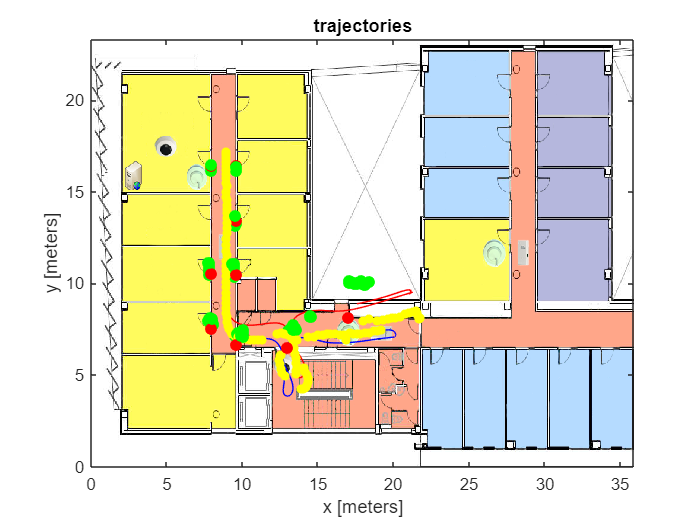

landmarks = [...
      7.934 16.431 0 1;...
      9.583 16.431 0 1;...
      9.584 13.444 0 1;...
      9.584 10.461 0 1;...
      7.973 10.534 0 1;...
      7.934  7.547 0 1;...
      9.584  6.654 0 1;...
     13.001  6.525 0 1;...
     17.007  8.136 0 1 ...
]';

Detected_landmarks = [];
Reference_landmarks = [];
Log_without_correction = [];

image(I,'XData',x_ima,'YData',y_ima);
axis xy
hold on

    plot(Pose_theoric(1,:), Pose_theoric(2,:), 'b')         % Display Pose_theoric
    plot(Pose_estimation(1,:), Pose_estimation(2,:), 'r')     % Display Pose_estimation
    title('trajectories'); 
    xlabel ('x [meters]'); 
    ylabel ('y [meters]');
    
    for time=3:length(l_s_b(:,1))
        
        Robot_pose = transl(Pose_estimation(1,time),Pose_estimation(2,time),0)*trotz(Pose_estimation(3,time));
    
        for landmark_index=1:length(landmarks(1,:))
            if l_s_b(time,landmark_index) ~= 0
                
                d=l_s_d(time,landmark_index);
                b=l_s_b(time,landmark_index);
                
                [X,Y]=pol2cart(b(1,1),d(1,1));
                
                L_w=Robot_pose*[X Y 0 1]';
                
                Detected_landmarks  = [Detected_landmarks L_w];
                Reference_landmarks = [Reference_landmarks landmarks(1:2,landmark_index)];         
            end
        end
        
        if ~isempty(Detected_landmarks)
            
            scatter(Reference_landmarks(1,:),Reference_landmarks(2,:), 50, 'r','filled');
            scatter(Detected_landmarks(1,:),Detected_landmarks(2,:), 50, 'g','filled');   
            
            A = []; 
            for i=1:size(Reference_landmarks, 2)
                A = [A;[Reference_landmarks(1,i),Reference_landmarks(2,i),1,0]];
                A = [A;[Reference_landmarks(2,i),-Reference_landmarks(1,i),0,1]];
            end
            
            B = [];
            for i=1:size(Detected_landmarks, 2)
                B = [B; Detected_landmarks(1,i); Detected_landmarks(2,i)];
            end
            
            Similarity_transform = linsolve(A,B);
            tx_ST = Similarity_transform(3);
            ty_ST = Similarity_transform(4);
            alpha_ST = atan2(Similarity_transform(2),Similarity_transform(1));

            Error = transl(-tx_ST,-ty_ST,0)*trotz(alpha_ST);
            Corrected_robot =  Error * [transl(Robot_pose); 1];
            scatter(Corrected_robot(1),Corrected_robot(2), 30, 'yellow','filled');
            
            % time stamp, estimated noisy pose, corrected position, number of Land-marks, and the errors.
            Single_log.Time_stamp = time;                                       % timestamp is the time (index)
            Single_log.Robot_pose = Robot_pose;                                 % estimated noisy pose
            Single_log.Corrected_robot = Corrected_robot;                       % corrected position
            Single_log.Number_of_landmarks = length(Detected_landmarks(1,:));   % number of landmarks
            Single_log.Error = Error;                                           % errors
            
            Log_without_correction = [Log_without_correction Single_log];
        end
        
        Detected_landmarks = [];
        Reference_landmarks = [];
    end
hold off

### Correct the noisy trajectory. 

To get an inspiration get familiar MR_SP_support.mlx

Pay attention to the relationship of the variables

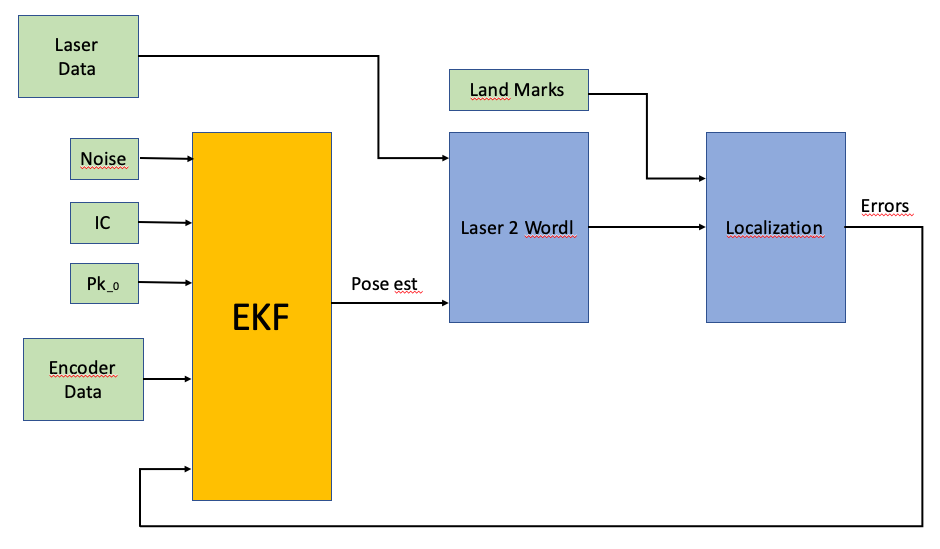

Update the estimated covarianze matrix by the sensor, knowing that the Laser scanner has and acuraccy 4 mm with a standard deviation of 0.2 mm.

1.- Display in a figure: the map, theoric trajectory (no noise) the noisy trajectory and the corrected trajectory.

2.- Make a 'log' with the following columns: time stamp, estimated noisy pose, corrected position, number of Land-marks,  and the errors. **The log that we have done is named Log_with_correction**

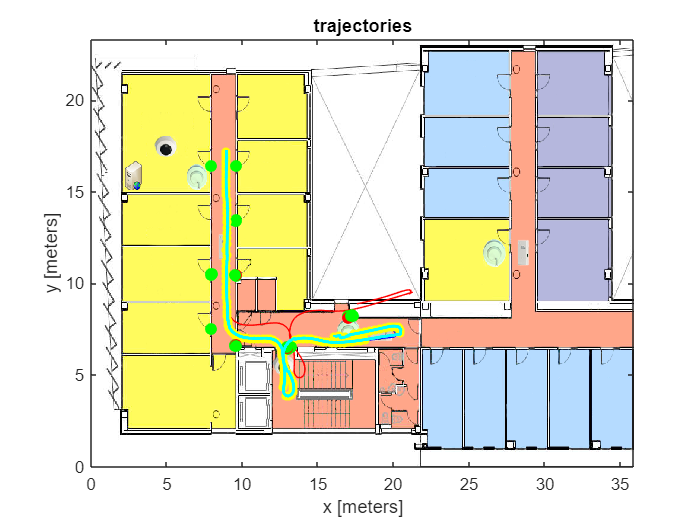

Detected_landmarks = [];
Reference_landmarks = [];
Log_with_correction = [];

Position_with_correction(:,1) = zeros(size(Pose_theoric(:,1)));
Position_with_correction(:,2) = Pose_theoric(:,2);

Orientation_with_correction = zeros(3004,1);
Orientation_with_correction(2) = Pose_theoric(3,2);
mu_noise = 0;
mu_laser = 0;
mu_fused = 0;

image(I,'XData',x_ima,'YData',y_ima);
axis xy
hold on

    plot(Pose_theoric(1,:), Pose_theoric(2,:), 'b')         % Display Pose_theoric
    plot(Pose_estimation(1,:), Pose_estimation(2,:), 'r')     % Display Pose_estimation
    title('trajectories'); xlabel ('x [meters]'); ylabel ('y [meters]')
    
    for time=3:length(l_s_b(:,1))
            
        Position_with_correction(1,time)  = Position_with_correction(1,time-1) + (delta_d(time)+noise_d)*cos(Orientation_with_correction(time-1));
        Position_with_correction(2,time)  = Position_with_correction(2,time-1) + (delta_d(time)+noise_d)*sin(Orientation_with_correction(time-1));
        Orientation_with_correction(time) = mod(Orientation_with_correction(time-1) + delta_t(time) + noise_t, 2*pi);
        
        Robot_pose = transl(Position_with_correction(1,time),Position_with_correction(2,time),0)*trotz(Orientation_with_correction(time));

        for landmark_index=1:length(landmarks(1,:))
            if l_s_b(time,landmark_index) > 0
                
                d=l_s_d(time,landmark_index);
                b=l_s_b(time,landmark_index);
                
                [X,Y]=pol2cart(b(1,1),d(1,1));
                
                L_w=Robot_pose*[X Y 0 1]';
                
                Detected_landmarks  = [Detected_landmarks L_w];
                Reference_landmarks = [Reference_landmarks landmarks(1:2,landmark_index)];         
            end
        end
        
        if ~isempty(Detected_landmarks)
            
            scatter(Reference_landmarks(1,:),Reference_landmarks(2,:), 50, 'r','filled');
            scatter(Detected_landmarks(1,:),Detected_landmarks(2,:), 50, 'g','filled');   
            
            A = []; 
            for i=1:size(Reference_landmarks, 2)
                A = [A;[Reference_landmarks(1,i),Reference_landmarks(2,i),1,0]];
                A = [A;[Reference_landmarks(2,i),-Reference_landmarks(1,i),0,1]];
            end
            
            B = [];
            for i=1:size(Detected_landmarks, 2)
                B = [B; Detected_landmarks(1,i); Detected_landmarks(2,i)];
            end
            
            Similarity_transform = linsolve(A,B);
            tx_ST = Similarity_transform(3);
            ty_ST = Similarity_transform(4);
            alpha_ST = atan2(Similarity_transform(2),Similarity_transform(1));
                
            Error = transl(-tx_ST,-ty_ST,0)*trotz(alpha_ST);
            Corrected_robot =  Error * [transl(Robot_pose); 1];
            scatter(Corrected_robot(1),Corrected_robot(2), 30, 'yellow','filled');
            Position_with_correction(1,time) = Corrected_robot(1);
            Position_with_correction(2,time) = Corrected_robot(2);
            
            %time stamp, estimated noisy pose, corrected position, number of Land-marks, and the errors.
                
            Single_log.Time_stamp = time;                                       % timestamp is the time (index)
            Single_log.Robot_pose = Robot_pose;                                 % estimated noisy pose
            Single_log.Corrected_robot = Corrected_robot;                       % corrected position
            Single_log.Number_of_landmarks = length(Detected_landmarks(1,:));   % number of landmarks
            Single_log.Error = Error;                                           % errors
            
            Log_with_correction = [Log_with_correction Single_log];
        end
            
        Detected_landmarks = [];
        Reference_landmarks = [];     
    end
    
    plot(Position_with_correction(1,2:end), Position_with_correction(2,2:end),'k','Color','c',"LineWidth",2)
    
hold off

## Mapping (40%)

This is part of the last TODO.

### Walls

Draw the *'walls/obstacles'  seeing by* the laser data. Do it only when Land Marks are avalaible and the trajectory have been corrected.

Make a movie erasing the previous walls after 200ms for better understanding.

See the video: '3_mapping.mp4' for inspiration

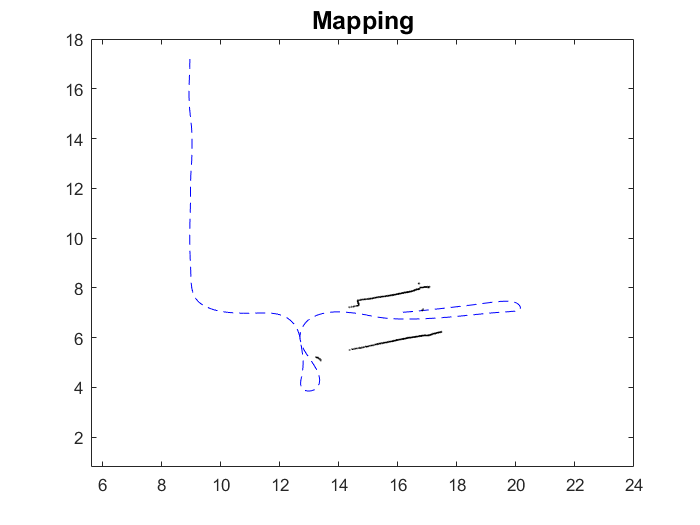

close all

video = VideoWriter('mapping2.avi');
video.FrameRate = 20;
video.Quality = 100;
open(video);
Robot = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];
visible = 0;
for k=1:3:(length(t)-1)
    clf
    plot(Pose_theoric(1,:), Pose_theoric(2,:), 'b--');
    xlim([5.6 24.0])
    ylim([0.8 18.0])
    hold on

    Robot_pose = transl(x(k), y(k), 0) * trotz(o(k));
    Robot_final = Robot_pose * Robot';

    rob = patch(Robot_final(1, :), Robot_final(2, :), 'r');
    
    if (mod(k, 6) == 1)
          clear x2 y2
        count = 1;
        m = size(polar_laser_data);
        i = ceil(k/20.1611);
        for j=1:(m(2)-1)
            if polar_laser_data(i, j) / 1000 > 0
                alpha = (j-1) * 0.3515;
                alpha = o(20 * (i-1) + 1) - 120 * pi/180 + alpha * pi/180;
                x2(count) = x(20 * (i-1) + 1) + (polar_laser_data(i, j) / 1000) * cos(alpha);
                y2(count) = y(20 * (i-1) + 1) + (polar_laser_data(i, j) / 1000) * sin(alpha);
                count = count + 1;
            end
        end
    end

    if mod(k, 20) == 0
        visible = 0;
        for i = 1:width(l_s_b)
            if visible == 0 && l_s_b(k, i) ~= 0
                P = landmarks(:, i);
                dist = sqrt( (x(k) - P(1))^2 + (y(k) - P(2))^2 );
                if dist <= 4
                    visible = 1;
                end  
            end
        end
    end

    if visible
        scatter(x2, y2, 1, '.', 'black');
    end
    title("Mapping", 'FontSize',15);
    pause(0.2)
    frame = getframe(gcf);
    writeVideo(video, frame);
    delete(rob);
end

close(video)

### Occupancy grid

Use Breshehan algorithm to build the map. Do it only when Land Marks are avalaible and the trajectory have been corrected.

Use the idea behind the line tracing: Visit: https://es.wikipedia.org/wiki/Algoritmo_de_Bresenham

See: Mapping.mlx and '4_occupancy.mp4' for inspiration

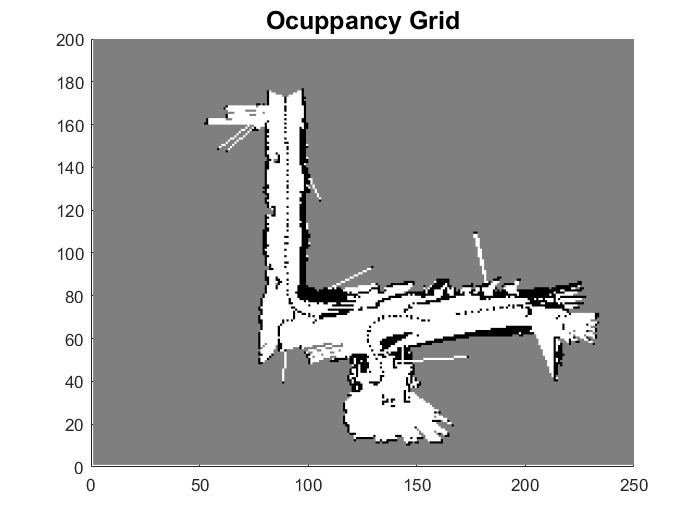

video = VideoWriter('Occupancy.avi');
video.FrameRate = 5;
video.Quality = 100;
open(video);

resolution = 10;
A = ones(20*resolution, 25*resolution);
for p=20:20:(length(t)-1)
    clear x2 y2 o2
    i = ceil(p/20.1611);
    count = 1;
    m = size(polar_laser_data);
    for j=1:(m(2)-1)
        if polar_laser_data(i, j) / 1000 > 0
            alpha = (j-1) * 0.3515;
            alpha = o(20 * (i-1) + 1) - 120 * pi/180 + alpha * pi/180;
            x2(count) = x(20 * (i-1) + 1) + (polar_laser_data(i, j) / 1000) * cos(alpha);
            y2(count) = y(20 * (i-1) + 1) + (polar_laser_data(i, j) / 1000) * sin(alpha);
            o2(count) = alpha;
            count = count + 1;
        end
    end
    
    for j = 1:(count-1)
        P_w = transl(0, 0, 0) * trotz(0) * [x2(j) y2(j) 0 1]';
        [X Y] = bresenham(x(p)*resolution, y(p)*resolution, P_w(1)*resolution, P_w(2)*resolution);
        l_xy = [X Y];
        L=height(l_xy);
        for k=1:L
            if l_xy(k, 1) > 0 && l_xy(k, 2) > 0
                if k == L
                    A(l_xy(k, 2),l_xy(k, 1)) = 0;
                else
                    A(l_xy(k, 2),l_xy(k, 1)) = 2;
                end
            end
        end
    end
    h = pcolor(A);
    h.EdgeColor = 'none';
    axis xy
    ylim([0 20*resolution]);
    xlim([0 25*resolution]);
    title("Ocuppancy Grid", 'FontSize',15);
    colormap(gray(3))
    pause(0.2)

    frame = getframe(gcf);
    writeVideo(video, frame);
end

close(video);